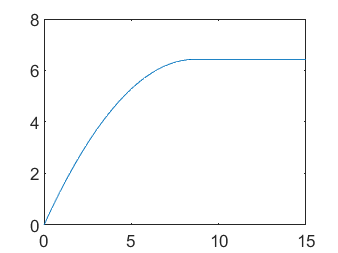

%shuffleboard-slakt
% % % 
tspan = [0 15];
v0 = 1.5;
n =100;
y0 = 0.45;

[x,v,t] = xeuler(@odeX,tspan,v0,n);
[y,vy,ty] = yeuler(@odeY,tspan,y0,n);



plot(t,x)

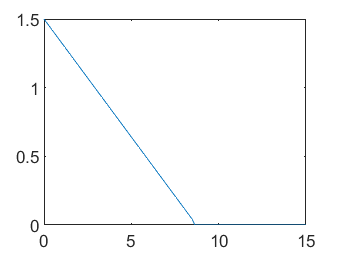

plot(t,v)

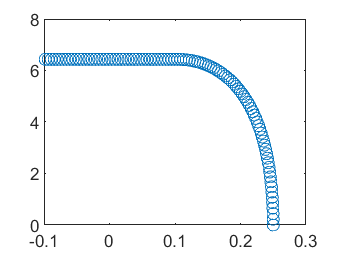


plot(y,x,'o')

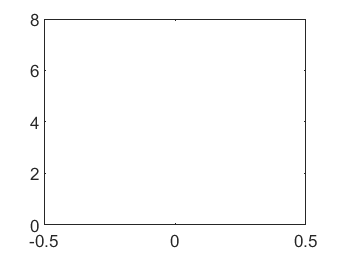


for i = 1:length(x)
    h = plot(y(i),x(i),'o r');            % draw something on the trajectory
    axis([-0.5 0.5 0 8])
    pause(0.01)                                % wait a minute
    delete(h)                                 % delete it
end
hold off